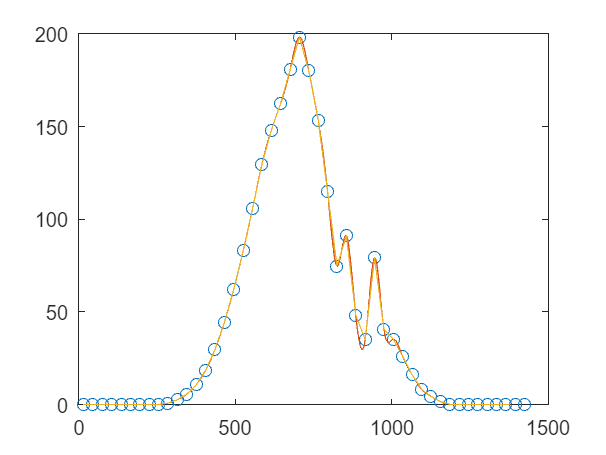

%Aufgabe 6 ÜZ1
clear all
load uv.mat
t_minuten = t*60;
ti = 15:23*60; % Wenn Schrittweite = 1 --> muss nicht angegeben werden
uv_inter = interp1(t_minuten, UVI, ti, "spline");
plot(t_minuten, UVI, 'o')
hold on
plot(ti, uv_inter)
hold on
uv_inter = interp1(t_minuten, UVI, ti, "linear");
plot(ti, uv_inter)

t_start = 12.5*60;
t_stop = 13.25*60;
uvi_fun = @(t) interp1(t_minuten, UVI, t, "linear")

uvi_fun = function_handle with value:
    @(t)interp1(t_minuten,UVI,t,"linear")


dosis_linear = integral(uvi_fun, t_start, t_stop)

dosis_linear = 6.4190e+03

dosis_spline = integral(uvi_fun, t_start, t_stop)

dosis_spline = 6.4190e+03